# Simulation with non-linear loads

In this livescript, we provide a tutorial to redo the simulations presented in *A time series distance measure for efficient clustering of input/output signals by their underlying dynamics*. As the results for the non-linear perturbations depend heavily on the type and severity of the non-linearity, we decided to not show results for a specific instantiation, but rather provide this tool so the interested reader can observe the effects of different linearities for themselves.

Consider the electrical circuit presented in the paper:

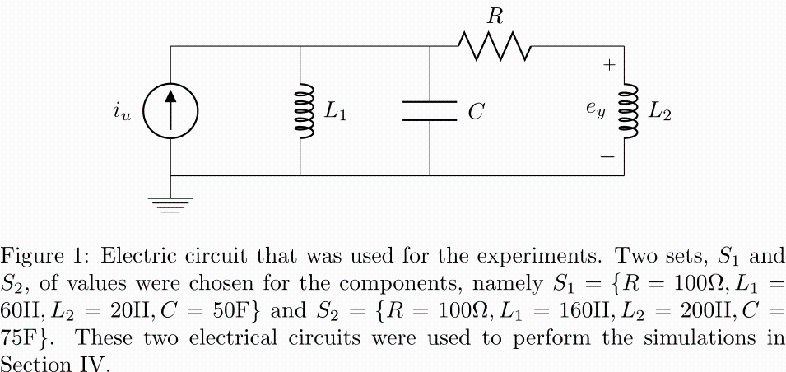.

Now, let us change the two linear inductors to saturated inductors. Since the Live Script (in the version of Matlab we are using) does not support local functions, the Matlab function implementing this type of inductor is provided in SL.m. For completeness, we copy  it here (in comments):

% function L = SL(i,max,a,b)
% %SL This function simulates a non-linear saturating inductor.
% %   i represents the current that flows through the inductor, max is the
% %   maximum value of inductance L, b is the value at which the inductor
% %   starts saturating, a is the value at which the inductor is completely
% %   saturated.
% L = 1;
% if (i > -a) && (i <= -b)
%     L = 1+((max-1)/abs(a-b))*(a+i);
% elseif (i > -b) && (i <= b)
%     L = max;
% elseif (i > b) && (i <= a)
%     L = 1 + ((max-1)/abs(a-b))*(a-i);
% end
% end

We can then plot this to show what the saturating inductor looks like:

% a defines the value at which the inductor is completely saturated
a = 5;
% b defines the value at which the inductor starts saturating
b = 3;
% max defines the maximum value of the inductance L, achieved when the inductor is not saturated at all
max = 20;
current = (-2*a:0.01:2*a);
L = zeros(size(current));
for j = 1:size(current,2)
    L(j) = SL(current(j),max,a,b);
end
plot(current,L)
axis([-2*a 2*a 0 2*max])

The inductor's saturation is thus defined by the values for *a* and *b* above, and is a hat function. Note that the inductance never reaches zero, but goes to one when the saturation is hit.

Referring back to Figure 1 above, we will use the different values for the L's as mentioned in the caption.

Now, let us generate input signals, just as we did in the linear case. Variations on these inputs can be implemented by the user. We will limit ourselves to a repetition over the following set-up of input: the output of two random systems driven by white noise, a corrupted sine wave, and random gaussian noise.

    N = 2^8;    %Length of the signals
    
    n = 3;    % Order of the input systems
    tolerance = 0.1;    % Tolerance against unstability (i.e., the poles and zeros should lie at least tolerance away from the unit circle)
    copies = 10;    % Number of different instantiations of the four input signals
    inputs = zeros(4*copies,N);
    time = 0:1:(N-1);
    
    for j = 1:copies
    
        % Initialize first input system, making sure the poles and zeros stay away from the unit circle.
        input1 = rss(n);
        [z, p, k] = zpkdata(input1,'v');
        while any(real(z)>-tolerance) || any(real(p)>-tolerance)
            input1 = rss(n);
            [z, p, k] = zpkdata(input1,'v');
            disp('Retried input1 because of zero or pole close to imaginary axis')
        end

        % Initialize second input system, making sure the poles and zeros stay away from the unit circle.
        input2 = rss(n);
        [z, p, k] = zpkdata(input2,'v');
        while any(real(z)>-tolerance) || any(real(p)>-tolerance)
            input2 = rss(n);
            [z, p, k] = zpkdata(input2,'v');
            disp('Retried input2 because of zero or pole close to imaginary axis')
        end
        
        % Generate inputs from the two systems
        inputs(4*(j-1)+1,:) = lsim(input1,100*rand*randn(N,1),time);
        inputs(4*(j-1)+2,:) = lsim(input2,100*rand*randn(N,1),time);
        
        % Generate corrupted sine wave
        inputs(4*(j-1)+3,:) = 100*idinput(N,'sine')+randn(N,1);
        
        % Generate random gaussian noise
        inputs(4*(j-1)+4,:) = 100*idinput(N,'rgs')+randn(N,1);

    end
    
inputs = [inputs;inputs];    

plot(inputs(1,:))
hold on
plot(inputs(2,:))
plot(inputs(3,:))
plot(inputs(4,:))
title('First four inputs')
xlabel('t')
ylabel('i(t)')
hold off

The system defined above is governed by the system equations (in ODE form), in function *ODE*.. Again, this is available in a separate file, due to the restrictions on local functions in the Live Script. We repeat it here (in comments) for completeness. We also show a function *generate_network*, which initializes an electric network like the one in Figure 1, with the different values for the components as variables.

% function network = generate_network(R1,C1,S1,S2)
% network = @(t,x,time,u) ODE(t,x,time,u,R1,C1,S1,S2);
% end

% % Dynamical equations of the system.
% function dX = ODE(t,x,time,u,R1,C1,S1,S2)
% uint = interp1(time,u,t);
% dX = zeros(4,1);
% dX(1) = (1/S1(x(1)))*x(2);
% dX(2) = -(1/C1)*x(1)-(1/C1)*x(3) + (1/C1)*uint;
% dX(3) = (1/S2(x(3)))*x(2) - (R1/S2(x(3)))*x(3);
% dX(4) = dX(2) - R1*dX(3);
% end

We now initialize the two networks with the component values defined above:

% Define the components of the two networks.
R11 = 100;
C11 = 50;
SL11 = @(i) SL(i,60,5,3);
SL12 = @(i) SL(i,20,5,3);

R21 = 100;
C21 = 75;
SL21 = @(i) SL(i,160,5,3);
SL22 = @(i) SL(i,200,5,3);

% Initialize networks
network1 = generate_network(R11,C11,SL11,SL12);
network2 = generate_network(R21,C21,SL21,SL22);

While for the linear case, we could just write down the state-space model and run *sim* or analogous commands, in the non-linear case, we have to do the integration by making use of *ode45*. 

We first define a function that allows us to set up a network with an input:

% % Add an input to the system.
% function network_with_input = set_input(network,u,time)
% network_with_input = @(t,x) network(t,x,time,u);
% end

We integrate system equations, and calculate the output. (For more info about the system equations, see the last example of [the course](http://lpsa.swarthmore.edu/Representations/SysRepSS.html) this example came from.) Note that this code uses some variables from the previous one, so be sure to run that one first.

    outputssys1 = zeros(4*copies, N);
    outputssys2 = zeros(4*copies, N);
    clusterid = zeros(4*copies,1);
    
for j = 1:copies
    
    % Initialize network 1 with first type of input
    network_with_input = set_input(network1,inputs(4*(j-1)+1,:),time);
    % Perform integration, save output and set clusterid for network 1 with first type of input
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys1(4*(j-1)+1,:) = states(:,4)';
    clusterid(4*(j-1)+1,:) = 1;
    % Do the same for the other types of input
    network_with_input = set_input(network1,inputs(4*(j-1)+2,:),time);
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys1(4*(j-1)+2,:) = states(:,4)';
    clusterid(4*(j-1)+2,:) = 1;
    
    network_with_input = set_input(network1,inputs(4*(j-1)+3,:),time);
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys1(4*(j-1)+3,:) = states(:,4)';
    clusterid(4*(j-1)+3,:) = 1;
    
    network_with_input = set_input(network1,inputs(4*(j-1)+4,:),time);
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys1(4*(j-1)+4,:) = states(:,4)';
    clusterid(4*(j-1)+4,:) = 1;
    
    % Similar for network 2
    
    network_with_input = set_input(network2,inputs(4*(j-1)+1,:),time);
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys2(4*(j-1)+1,:) = states(:,4)';
    clusterid(4*copies + 4*(j-1)+1,:) = 2;
   
    network_with_input = set_input(network2,inputs(4*(j-1)+2,:),time);
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys2(4*(j-1)+2,:) = states(:,4)';
    clusterid(4*copies + 4*(j-1)+2,:) = 2;
    
    network_with_input = set_input(network2,inputs(4*(j-1)+3,:),time);
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys2(4*(j-1)+3,:) = states(:,4)';
    clusterid(4*copies + 4*(j-1)+3,:) = 2;
    
    network_with_input = set_input(network2,inputs(4*(j-1)+4,:),time);
    [t,states] = ode45(network_with_input, time, zeros(4,1));
    outputssys2(4*(j-1)+4,:) = states(:,4)';
    clusterid(4*copies + 4*(j-1)+4,:) = 2;

end

outputs = [outputssys1;outputssys2];
    

plot(outputs(1,:))
hold on
plot(outputs(2,:))
plot(outputs(3,:))
plot(outputs(4,:))
title('First four outputs of system 1')
xlabel('t')
ylabel('e(t)')
hold off

plot(outputs(4*copies+1,:))
hold on
plot(outputs(4*copies+2,:))
plot(outputs(4*copies+3,:))
plot(outputs(4*copies+4,:))
title('First four outputs of system 2')
xlabel('t')
ylabel('e(t)')
hold off

We now have two variables, *inputs* and *outputs*, which we can use to cluster input/output-pairs. Inputs repeats the inputs twice, outputs first has all outputs belonging to the first circuit, then all outputs belonging to the second circuit. They are constructed in such a way that the input at *inputs(j)* corresponds to the input for the output at *outputs(j)*, for any *j*.

Now, we calculate the cepstra of these signal pairs:

[n,k] = size(outputs);

     if (k > 2^7)    % If the signals are of reasonable length, Welch's method is good enough to estimate the PSD. If not, use multitaper method.
        InputCeps = zeros(n,size(ifft(log(pwelch(inputs(1,:),[],[],'twosided')),'symmetric'),1));
        OutputCeps = zeros(n,size(ifft(log(pwelch(outputs(1,:),[],[],'twosided')),'symmetric'),1));
        cepstrumcutoff = floor(size(ifft(log(pwelch(outputs(1,:),[],[],'twosided')),'symmetric'),1));
        weights = 1:1:cepstrumcutoff-1;
        for i = 1:n
            InputCeps(i,:) = ifft(log(pwelch(inputs(i,:),[],[],'twosided')),'symmetric');
            OutputCeps(i,:) = ifft(log(pwelch(outputs(i,:),[],[],'twosided')),'symmetric');
        end
        disp('Welch')
     else
        InputCeps = zeros(n,size(ifft(log(pmtm(inputs(1,:),'twosided')),'symmetric'),1));
        OutputCeps = zeros(n,size(ifft(log(pmtm(outputs(1,:),'twosided')),'symmetric'),1));
        cepstrumcutoff = floor(size(ifft(log(pmtm(outputs(1,:),'twosided')),'symmetric'),1));
        weights = 1:1:cepstrumcutoff-1;
            for i = 1:n
            InputCeps(i,:) = ifft(log(pmtm(inputs(i,:),'twosided')),'symmetric');
            OutputCeps(i,:) = ifft(log(pmtm(outputs(i,:),'twosided')),'symmetric');
            end
        disp('mtm')
     end

We can now compare clustering results for different distance measures. Each code block below will calculate results for a different distance, plot the distance matrix (whichshould contain black squares in the top-left and bottom-right corners, and white squares in the other corners for a perfect clustering), and give the ARI (the ARI is calculated by another function that is available alongside this Live Script).

% Euclidean distance
normoutputs = zscore(outputs')';
norminputs = zscore(inputs')';

DistOutput = squareform(pdist(normoutputs));
DistInput = squareform(pdist(norminputs));
% Change alpha to a number between 0 and 1 to explicitly add a cost term involving the input to the Euclidean distance.
alpha = 0;
DistEuclid = (1-alpha)*DistOutput + alpha*DistInput;
VectorEuclid = squareform(DistEuclid);

figure
colormap('gray')
imagesc(DistEuclid);
colorbar;
title('Euclidean Distance Matrix');

Zeuclid = linkage(VectorEuclid);
ceuclid = cluster(Zeuclid,'maxclust',2);
ARI = adjrandindex(ceuclid,clusterid)

The following block of code calculates the lower bound to DTW. The external function dLB (made by Quan Wang) is needed.

% Lower bound on DTW distance
normoutputs = zscore(outputs')';
norminputs = zscore(inputs')';

DistLB = zeros(n,n);
w=floor(k*(5/100));
    for i = 1:n
        for j = 1:i-1
             DistLB(i,j) = dLB(normoutputs(i,:)', normoutputs(j,:)', 1);
             DistLB(j,i) = DistLB(i,j);
        end
    end
VectorLB = squareform(DistLB);
        
% Alternatively, change the previous with the following to add the inputs in explicitly.
% This was not done by default as it increases computation time.
%         alpha = 0.5;
%         DistLBOutputs = zeros(n,n);
%         DistLBInputs = zeros(n,n);
%         w=floor(k*(5/100));
%             for i = 1:n
%                 for j = 1:i-1
%                      DistLBOutputs(i,j) = dLB(normoutputs(i,:)', normoutputs(j,:)', 1);
%                      DistLBOutputs(i,j) = DistLBOutputs(i,j)(i,j);
%                      DistLBInputs(i,j) = dLB(norminputs(i,:)', norminputs(j,:)', 1);
%                      DistLBInputs(j,i) = DistLBInputs(i,j);
%                 end
%             end
%         VectorLB = squareform((1-alpha)*DistLBOutputs(i,j) + alpha*DistLBInputs);

figure
colormap('gray')
imagesc(DistLB);
colorbar;
title('DTW LB Distance Matrix');

ZLB = linkage(VectorLB);
cLB = cluster(ZLB,'maxclust',2);
ARI = adjrandindex(cLB,clusterid)

The next block of code calculates the original cepstral distance.

%% Original cepstral distance
DistCepstral = zeros(n,n);

for i = 1:n

    for j = 1:i-1

        DistCepstral(i,j) = weights*((OutputCeps(i,2:cepstrumcutoff)' - OutputCeps(j,2:cepstrumcutoff)').^2);
        DistCepstral(j,i) = DistCepstral(i,j);
    end
end

VectorCepstral = squareform(DistCepstral);

figure
colormap('gray')
imagesc(DistCepstral);
colorbar;
title('Original Cepstral Distance Matrix');

Zcepstral = linkage(VectorCepstral);
ccepstral = cluster(Zcepstral,'maxclust',2);
ARI = adjrandindex(ccepstral,clusterid)

The next block of code calculates the extended cepstral distance.

%% Extended cepstral distance
DistExtended = zeros(n,n);

for i = 1:n

    for j = 1:i-1

        DistExtended(i,j) = weights*(((OutputCeps(i,2:cepstrumcutoff) - InputCeps(i,2:cepstrumcutoff))' - (OutputCeps(j,2:cepstrumcutoff) - InputCeps(j,2:cepstrumcutoff))').^2);
        DistExtended(j,i) = DistExtended(i,j);
    end
end

VectorExtended = squareform(DistExtended);

figure
colormap('gray')
imagesc(DistExtended);
colorbar;
title('Extended Cepstral Distance Matrix');

Zextended = linkage(VectorExtended);
cextended = cluster(Zextended,'maxclust',2);
ARI = adjrandindex(cextended,clusterid)

Estimate transfer function models.

systems = cell(n,1);
opt = tfestOptions;
opt.Advanced.StabilityThreshold.z = 1-10^(-2);
for i = 1:n
    Y = iddata(outputs(i,:)',inputs(i,:)',1);
    systems{i} = tfest(Y,5,[],NaN,'Ts',Y.Ts,opt);
end

Calculate H2 norm-based distance.

DistH2 = zeros(n,n);

for i = 1:n
    j = i+1;
    while j<=n

        DistH2(i,j) = norm(systems{i}-systems{j});
        DistH2(j,i) = DistH2(i,j);
        j = j+1;
    end
end

VectorH2 = squareform(DistH2);

figure
colormap('gray')
imagesc(DistH2);
colorbar;
title('H2 norm-based Distance Matrix');


ZH2 = linkage(VectorH2);
cH2 = cluster(ZH2,'maxclust',2);
ARI = adjrandindex(cH2,clusterid)

Calculate H-infinity norm-based distance

DistHInf = zeros(n,n);

for i = 1:n
    j = i+1;
    while j<=n

        DistHInf(i,j) = norm(systems{i}-systems{j},Inf);
        DistHInf(j,i) = DistHInf(i,j);
        j = j+1;
    end
end

VectorHInf = squareform(DistHInf);

figure
colormap('gray')
imagesc(DistHInf);
colorbar;
title('HInf norm-based Distance Matrix');

ZHInf = linkage(VectorHInf);
cHInf = cluster(ZHInf,'maxclust',2);
ARI = adjrandindex(cHInf,clusterid)